# HW1

## PROBLEM 1

## a. Plot

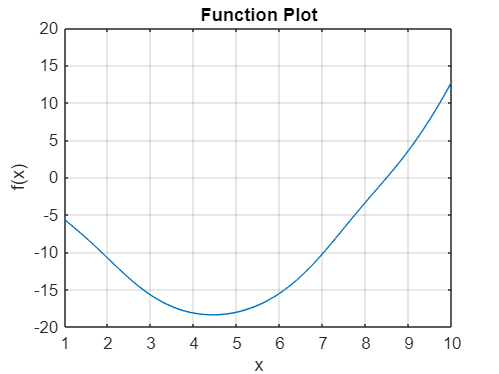

syms x;
f = x.^2 - 9*x + exp(sin(x)) + log(x);
x_val = linspace(1, 10);
f_numerical = matlabFunction(f);
plot(x_val, f_numerical(x_val));
xlim([1 10]);
ylim([-20 20]);
xticks(1:10);
xlabel("x");
ylabel("f(x)");
title("Function Plot");
grid('on');

interval_length = zeros(4, 15);

## b. Golden Search

a0 = x_val(1);
b0 = x_val(end);
phi = (3 - sqrt(5)) / 2;
a1 = a0 + phi * (b0 - a0);
b1 = b0 - phi * (b0 - a0);
for i = 1:15
    value_a1 = f_numerical(a1);
    value_b1 = f_numerical(b1);
    if value_b1 > value_a1
        interval1 = [a0, b1];
        b0 = b1;
    else
        interval1 = [a1, b0];
        a0 = a1;
    end
    interval_length(1, i) = interval1(2) - interval1(1);
    a1 = a0 + phi * (b1 - a0);
    b1 = b0 - phi * (b1 - a0);
    fprintf('Iteration %d: f(a1) = %.6f, f(b1) = %.6f, Uncertainty Interval: [%.6f, %.6f]\n', i, value_a1, value_b1, interval1(1), interval1(2));
end

Iteration 1: f(a1) = -18.374049, f(b1) = -12.798350, Uncertainty Interval: [1.000000, 6.562306]
Iteration 2: f(a1) = -16.201872, f(b1) = -18.374049, Uncertainty Interval: [3.124612, 6.562306]
Iteration 3: f(a1) = -17.570622, f(b1) = -15.210180, Uncertainty Interval: [3.124612, 6.060753]
Iteration 4: f(a1) = -18.330216, f(b1) = -18.082422, Uncertainty Interval: [3.124612, 4.939247]
Iteration 5: f(a1) = -17.910026, f(b1) = -18.330216, Uncertainty Interval: [3.817741, 4.939247]
Iteration 6: f(a1) = -18.124418, f(b1) = -18.241893, Uncertainty Interval: [3.981366, 4.939247]
Iteration 7: f(a1) = -18.346058, f(b1) = -18.328759, Uncertainty Interval: [3.981366, 4.635868]
Iteration 8: f(a1) = -18.323223, f(b1) = -18.370747, Uncertainty Interval: [4.231364, 4.635868]
Iteration 9: f(a1) = -18.348072, f(b1) = -18.351814, Uncertainty Interval: [4.290380, 4.635868]
Iteration 10: f(a1) = -18.372255, f(b1) = -18.365088, Uncertainty Interval: [4.290380, 4.526446]
Iteration 11: f(a1) = -18.370051, f(b1)

## c. Fibonacci Method

a0 = x_val(1);
b0 = x_val(end);
a1 = a0 + phi * (b0 - a0);
b1 = b0 - phi * (b0 - a0);
for i = 1:15
    value_a1 = f_numerical(a1);
    value_b1 = f_numerical(b1);
    if value_b1 > value_a1
        interval2 = [a0, b1];
        b0 = b1;
    else
        interval2 = [a1, b0];
        a0 = a1;
    end
    interval_length(2, i) = interval2(2) - interval2(1);
    phi = 1 - (fibonacci(16-i) / fibonacci(17-i));
    a1 = a0 + phi * (b1 - a0);
    b1 = b0 - phi * (b1 - a0);
    fprintf('Iteration %d: f(a1) = %.6f, f(b1) = %.6f, Uncertainty Interval: [%.6f, %.6f]\n', i, value_a1, value_b1, interval2(1), interval2(2));
end

Iteration 1: f(a1) = -18.374049, f(b1) = -12.798350, Uncertainty Interval: [1.000000, 6.562306]
Iteration 2: f(a1) = -16.201863, f(b1) = -18.374049, Uncertainty Interval: [3.124609, 6.562306]
Iteration 3: f(a1) = -17.570624, f(b1) = -15.210195, Uncertainty Interval: [3.124609, 6.060750]
Iteration 4: f(a1) = -18.330210, f(b1) = -18.082415, Uncertainty Interval: [3.124609, 4.939253]
Iteration 5: f(a1) = -17.910050, f(b1) = -18.330210, Uncertainty Interval: [3.817756, 4.939253]
Iteration 6: f(a1) = -18.124414, f(b1) = -18.241873, Uncertainty Interval: [3.981362, 4.939253]
Iteration 7: f(a1) = -18.346077, f(b1) = -18.328782, Uncertainty Interval: [3.981362, 4.635818]
Iteration 8: f(a1) = -18.323165, f(b1) = -18.370755, Uncertainty Interval: [4.231245, 4.635818]
Iteration 9: f(a1) = -18.348076, f(b1) = -18.351871, Uncertainty Interval: [4.290391, 4.635818]
Iteration 10: f(a1) = -18.372223, f(b1) = -18.365024, Uncertainty Interval: [4.290391, 4.526759]
Iteration 11: f(a1) = -18.370153, f(b1)

## d. Bisection Method

a0 = x_val(1);
b0 = x_val(end);
x0 = (b0 + a0) / 2;
df = matlabFunction(diff(f, 1));
for i = 1:15
    df_val = df(x0);
    if df_val > 0
        interval3 = [a0, x0];
    elseif df_val < 0
        interval3 = [x0, b0];
    else
        fprintf("Iteration %d: f'(x0) = %.6f, Minimizer = %.6f", i, df_val, x0);
        break;
    end
    interval_length(3, i) = interval3(2) - interval3(1);
    a0 = interval3(1);
    b0 = interval3(end);
    x0 = (b0 + a0) / 2;
    fprintf("Iteration %d: f'(x0) = %.6f, Uncertainty Interval: [%.6f, %.6f]\n", i, df_val, interval3(1), interval3(2));
end

Iteration 1: f'(x0) = 2.531789, Uncertainty Interval: [1.000000, 5.500000]
Iteration 2: f'(x0) = -3.084492, Uncertainty Interval: [3.250000, 5.500000]
Iteration 3: f'(x0) = -0.150268, Uncertainty Interval: [4.375000, 5.500000]
Iteration 4: f'(x0) = 1.161746, Uncertainty Interval: [4.375000, 4.937500]
Iteration 5: f'(x0) = 0.506591, Uncertainty Interval: [4.375000, 4.656250]
Iteration 6: f'(x0) = 0.179383, Uncertainty Interval: [4.375000, 4.515625]
Iteration 7: f'(x0) = 0.014989, Uncertainty Interval: [4.375000, 4.445312]
Iteration 8: f'(x0) = -0.067516, Uncertainty Interval: [4.410156, 4.445312]
Iteration 9: f'(x0) = -0.026234, Uncertainty Interval: [4.427734, 4.445312]
Iteration 10: f'(x0) = -0.005616, Uncertainty Interval: [4.436523, 4.445312]
Iteration 11: f'(x0) = 0.004689, Uncertainty Interval: [4.436523, 4.440918]
Iteration 12: f'(x0) = -0.000463, Uncertainty Interval: [4.438721, 4.440918]
Iteration 13: f'(x0) = 0.002113, Uncertainty Interval: [4.438721, 4.439819]
Iteration 14: f

## e. Newton's Method

x_k = 7;
df = matlabFunction(diff(f));
ddf = matlabFunction(diff(f, 2));
for i = 1:15
    x_k = x_k - df(x_k) / ddf(x_k);
    x = x_k - df(x_k) / ddf(x_k);
    interval_length(4, i) = abs(x - x_k);
    if df(x) == 0
        fprintf("Iteration %d: Minimizer: %.15f\n", i, x);
    end
    fprintf("Iteration %d: Value of x: %.15f\n", i, x);

end

Iteration 1: Value of x: 4.329200051725151
Iteration 2: Value of x: 4.438326488104302
Iteration 3: Value of x: 4.438918199685141
Iteration 4: Value of x: 4.438918213100447
Iteration 5: Value of x: 4.438918213100448
Iteration 6: Value of x: 4.438918213100447
Iteration 7: Value of x: 4.438918213100448
Iteration 8: Value of x: 4.438918213100447
Iteration 9: Value of x: 4.438918213100448
Iteration 10: Value of x: 4.438918213100447
Iteration 11: Value of x: 4.438918213100448
Iteration 12: Value of x: 4.438918213100447
Iteration 13: Value of x: 4.438918213100448
Iteration 14: Value of x: 4.438918213100447
Iteration 15: Value of x: 4.438918213100448


## f. Plot of the interval lengths

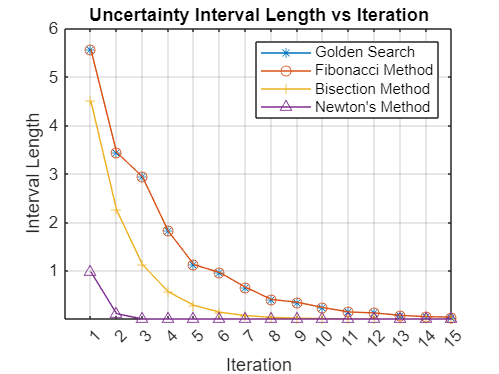

figure;
plot(interval_length(1, :), '-*');
hold on
plot(interval_length(2, :), '-o');
plot(interval_length(3, :), '-+');
plot(interval_length(4, :), '-^');
xticks(1:15);
yticks(1:10);
xlabel("Iteration");
ylabel("Interval Length");
title("Uncertainty Interval Length vs Iteration");
legend("Golden Search", "Fibonacci Method", "Bisection Method", "Newton's Method");
grid('on');

## g. Table

iterations = [1, 5, 10, 15];
methods = ["Golden Search", "Fibonacci Method", "Bisection Method", "Newton's Method"];
T = array2table(interval_length(:, iterations), 'VariableNames', "iteration= "+string(iterations), 'RowNames', methods);
disp(T);

                        iteration= 1    iteration= 5    iteration= 10    iteration= 15
                        ____________    ____________    _____________    _____________

    Golden Search          5.5623            1.1215         0.23607         0.040653  
    Fibonacci Method       5.5623            1.1215         0.23637         0.037501  
    Bisection Method          4.5           0.28125       0.0087891       0.00027466  
    Newton's Method       0.97673        8.8818e-16      8.8818e-16       8.8818e-16  



## PROBLEM 2

## **Secant Method**

g = @(x) x*tan(3*x) + 2 * x.^3 + 1;
x_k0 = 0;
x_k = 1;
epsilon = 10^-5;
while abs(x_k - x_k0) >= epsilon
    x = x_k - (x_k - x_k0) * g(x_k) / (g(x_k) - g(x_k0));
    x_k0 = x_k;
    x_k = x;
end
fprintf("Root of g: %d\nValue of g at root x: %d", x, g(x));

Root of g: 6.559373e-01
Value of g at root x: 7.639287e-10